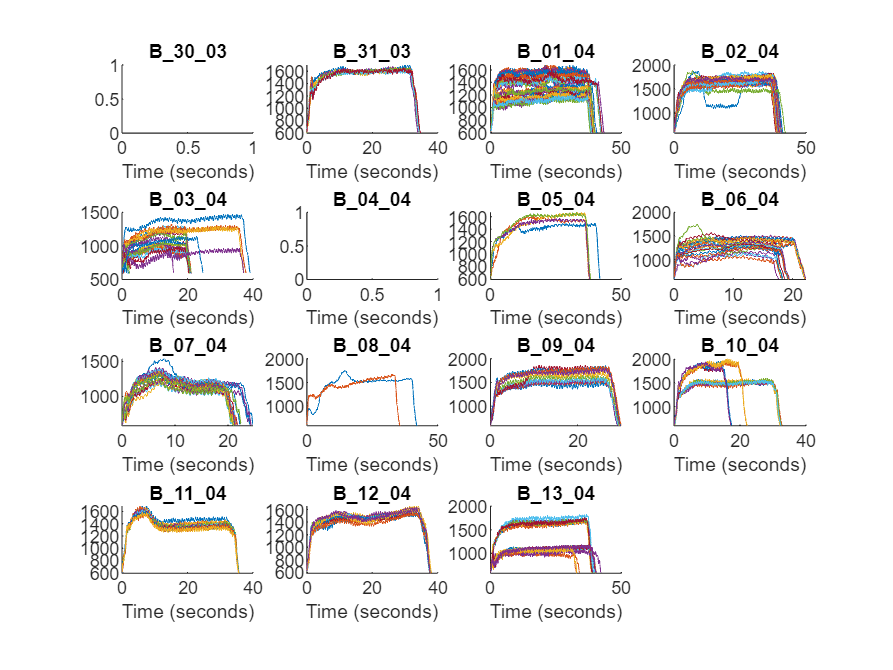

LoadRawData();

pulseThreshold = 600; % Threshold for state detection given by company
minPulseTimeThreshold = 500; % Samples

% Loop through the files, load the data the perform the state detection
% Extract the pulses for each sensor signal based on Signal 20
fig = figure();
%title(fig, "Identified pulses on signal 21:20");
signalNumberForDetection = 5;
signalNumberToPlot = 5; % This is signal 21:20
[~,numOfFiles] = size(filenames);
mask = {numOfFiles};
flag = {numOfFiles};
pulseData = {numOfFiles};
rawDataArray = {numOfFiles};
totalPulses = 1;
for fileIndex=1:numOfFiles
    % Load the data for the current file
    rawDataStruct = load(subfolder + filenames(fileIndex) + ".mat");
    rawDataArray{fileIndex} = struct2array(rawDataStruct); 

    %pulses is a 2D array with dimensions (1 * numOfPulses)
    [pulseData{fileIndex}, mask{fileIndex}, flag{fileIndex}, maxPulseLengths(fileIndex)] = fnStateDetection(rawDataArray{fileIndex}, pulseThreshold, minPulseTimeThreshold, signalNumberForDetection);
    
    % Plot the extracted Signal 20 pulses for this particular file
    subplot(4, 4, fileIndex);
    hold on;
    [~, numOfPulses] = size(pulseData{fileIndex});
    for pulseIndex=1:numOfPulses
        x = pulseData{fileIndex}{pulseIndex}(:, signalNumberToPlot);
        t = 0 : Ts : (Ts * size(x, 1) - Ts);
        plot(t, x);
    end
    title(filenames(fileIndex), 'Interpreter', 'none');
    xlabel("Time (seconds)");

    % Combine the pulse data for this file with all the others    
    for pulseIndex = 1:numOfPulses
        if flag{fileIndex}(pulseIndex) == false % Only include pulses that aren't marked as potential false ones
            for sensorIndex = 1:numOfSignals % Add data for each sensor
                tempData = pulseData{fileIndex}{pulseIndex}(:, sensorIndex);
                pulseData_Timetable{totalPulses, sensorIndex} = timetable(tempData, 'SampleRate', 1/Ts, 'VariableNames', sensorNames(sensorIndex));
            end
            totalPulses = totalPulses + 1;
        end
    end
end

clear x;

print -depsc 'Thesis\figures\IdentifiedPulsesFig';

%% Remove DC Offset
%% Pad to the length of longest pulse
maxPulseLength = max(maxPulseLengths) + 1;
for fileIndex = 1:numOfFiles
    for pulseIndex = 1:size(pulseData{fileIndex},2)
        temp = pulseData{fileIndex}{pulseIndex};
        numSamplesUnderMax = maxPulseLength - size(temp, 1);
        pulseData_DcRemoved{fileIndex}{pulseIndex} = temp - mean(temp, 1);
        pulseData_Padded{fileIndex}{pulseIndex} = padarray (temp, numSamplesUnderMax, 12, "post");
        temp2 = pulseData_Padded{fileIndex}{pulseIndex};
        pulseData_DcRemovedPadded{fileIndex}{pulseIndex} = temp2 - mean(temp2, 1);
    end
end
clear temp;
clear temp2;

%% Combine the data for all padded pulses
totalPulses = 1;
for fileIndex=1:numOfFiles
    for pulseIndex = 1:size(pulseData{fileIndex},2)
        if flag{fileIndex}(pulseIndex) == false % Only include pulses that aren't marked as potential false ones
            for sensorIndex = 1:numOfSignals % Add data for each sensor
                tempData = pulseData_Padded{fileIndex}{pulseIndex}(:, sensorIndex);
                pulseData_Timetable_Padded{totalPulses, sensorIndex} = timetable(tempData, 'SampleRate', 1/Ts, 'VariableNames', sensorNames(sensorIndex));
                tempData = pulseData_DcRemoved{fileIndex}{pulseIndex}(:, sensorIndex);
                pulseData_Timetable_DcRemoved{totalPulses, sensorIndex} = timetable(tempData, 'SampleRate', 1/Ts, 'VariableNames', sensorNames(sensorIndex));
                tempData = pulseData_DcRemoved{fileIndex}{pulseIndex}(:, sensorIndex);
                pulseData_Timetable_DcRemovedPadded{totalPulses, sensorIndex} = timetable(tempData, 'SampleRate', 1/Ts, 'VariableNames', sensorNames(sensorIndex));
            end
            totalPulses = totalPulses + 1;
        end
    end
end
clear fileIndex;
clear pulseIndex;
clear tempData;

## Plot padded data

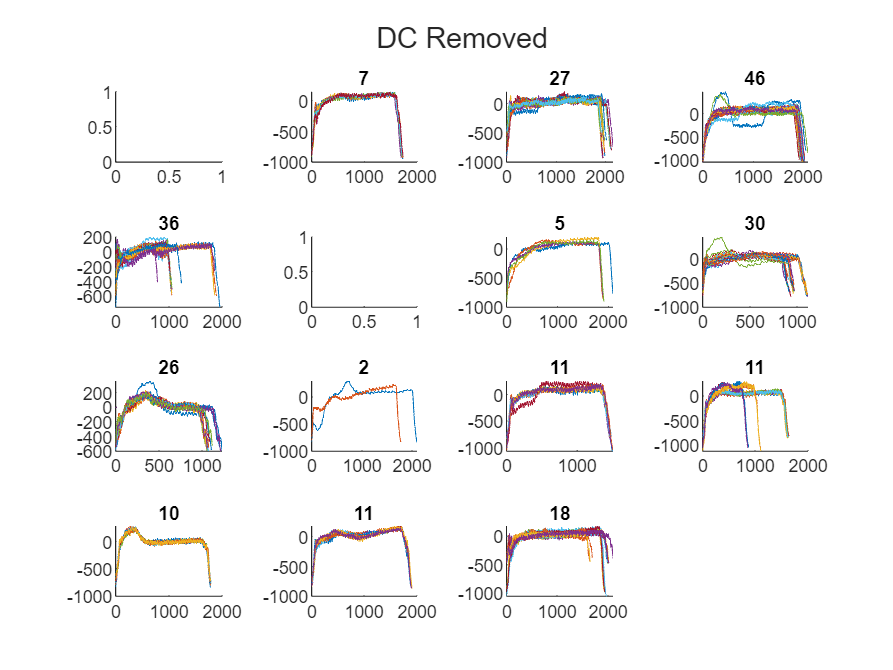

figure();
fig = tiledlayout(4, 4);
%title(fg, 'Padded data');
title(fig, 'DC Removed');
for fileIndex=1:numOfFiles
    %subplot(4, 4, fileIndex); 
    nexttile; hold on;
    for pulseIndex = 1:size(pulseData_Padded{fileIndex},2)
        %plot( pulseData_Padded{fileIndex}{pulseIndex}(:,5) );
        plot( pulseData_DcRemoved{fileIndex}{pulseIndex}(:,5) );
        title( pulseIndex );
    end
end

clear fileIndex;
clear pulseIndex;
clear fig;

## Plot the state detection signal vs 21:20 Actual Moment under Rollers

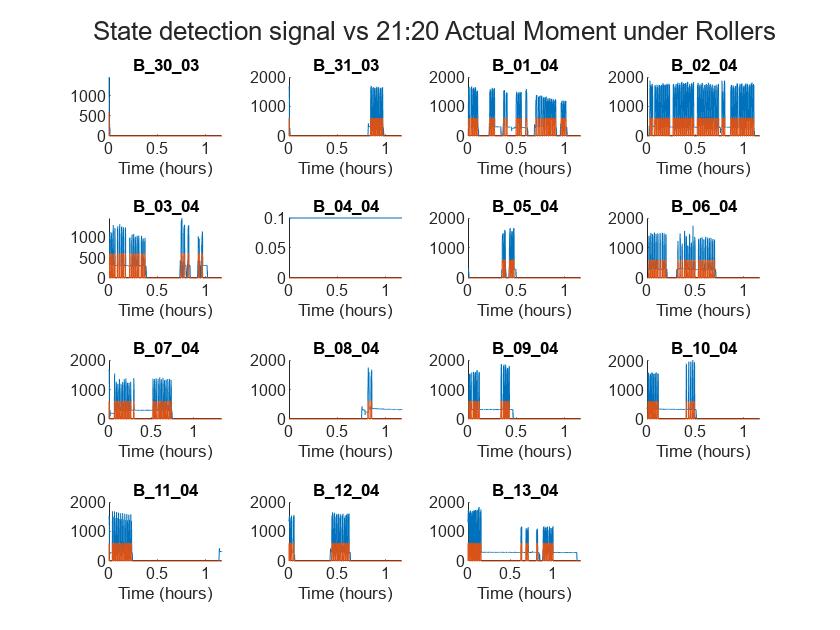

figure();
fig = tiledlayout(4, 4);
title(fig, 'State detection signal vs 21:20 Actual Moment under Rollers');
for fileIndex=1:numOfFiles
    nexttile; hold on;
    x = cell2mat(rawDataArray{fileIndex}(signalNumberToPlot, 2));
    t = 0 : Ts / 3600 : (Ts * size(x, 1) - Ts) / 3600;
    plot(t, x');
    plot(t, mask{fileIndex});
    title(filenames(fileIndex), 'Interpreter', 'none');
    xlabel("Time (hours)");
end
clear fig;
clear fileIndex;
clear t;
print -depsc 'Thesis\figures\StateDetectionFig';